# Quadcopter Model

## Learning Goals

After completing this module the student will be able to:

Describe the classes of motions of a quadcopter

- Write and explain the equations for the forces generated by the propellers

- Predict the motion of the quadcopter under activations of the propellers

- Use the Symbolic Toolbox to implement equations

- Apply MATLAB functions to generate a MATLAB Function block

- Construct a function for propeller activation to achieve a hover

- Explain the need for a control system

## Introduction

In this module, you will focus on what will be referred to as the "Quadcopter".   In the previous lesson, you learned about the Airframe, which captured the equations of motion and the underlying physics.   The input to the Airframe were applied forces and torques operating on the center of mass, along with factors from the environment, including gravity.    Key parameters required included the mass and moments of inertial.    In the Quadcopter, you will add the basic configuration of the motors and propellers and given input of the velocity of each propeller, calculate the forces and torques that the Airframe needed.  As a result, your model is getting one step closer to the actual quadcopter hardware.

The additional of the propeller and motor function is depicted in the figure below.

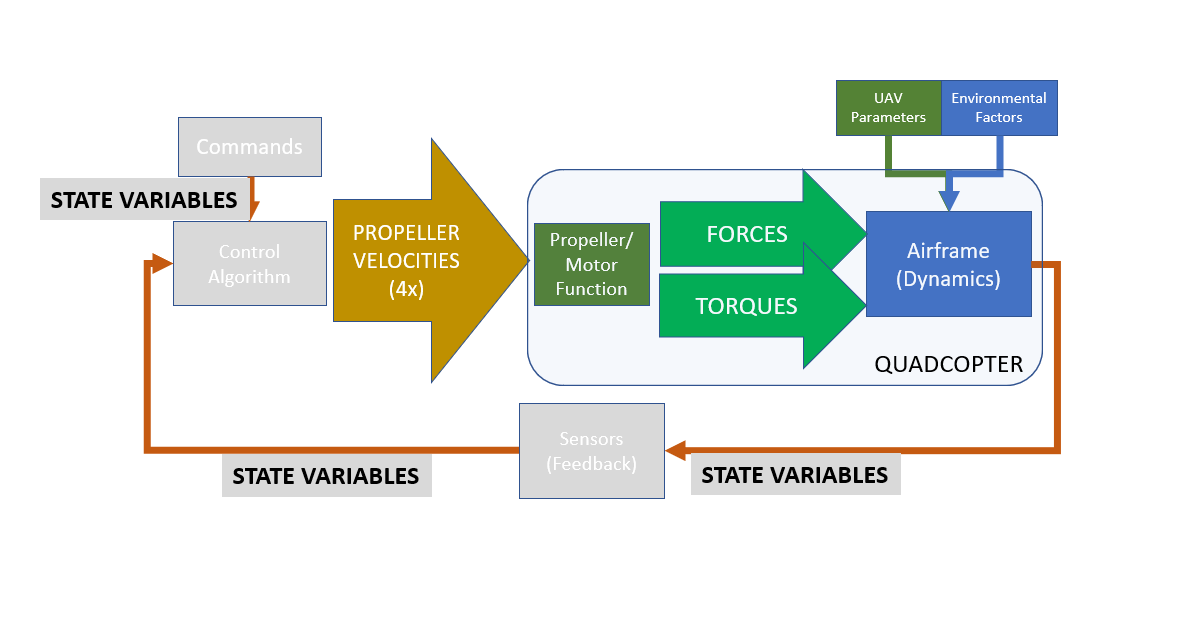

## Propeller Force Generation

When a propeller spins, it forces air to flow in along the axis of rotation.   That airflow creates a force that is used by the vehicle to "propel" it in the opposite direction.   the precise force created depends on the number of the propeller blades, their size and shape, and also the speed with which they spin.   

### Theoretical Power   

(reference:   [JustDrones](https://justdrones.com.au/how-much-power-is-needed-to-hover/) )

The relationship of the propeller shape and dimensions to the the power needed to spin the propeller fast enough for flight is explained in many references, including the one mentioned above.   The design of a propeller is beyond the scope of this lesson, but it is important to note a few items.

- The power of  of moving air is related to the density of the air moving, the cross-sectional area of the propeller, and the velocity of the air raised to the power of three.    $P=\frac{1}{2}Q_{\textrm{air}} \left(\pi r^2 \right)v^3$

- The power of a system that exerts a force F on an object that is moved with a velocity v is $P=F\;v$

From this you obtain the relationship you need.

- 
$$F=\frac{1}{2}Q_{\textrm{air}} \left(\pi r^2 \right)v^2$$


### Force and Torque Equations Necessary for Your Model

For your purposes, you do not need to know all of these factors.    The actual power delivered by the propellers will be slightly different than the equation specifies due to losses in the system, but this is not important to this discussion.   What is important is that the force is proportional to the square of the velocity, and correspondingly to the square of the angular velocity the propeller is spinning.

A propeller that is spinning about its axis at an angular velocity of $\omega$ creates a force that is proportional to the square of the angular velocity and a torque that is also proportional to the angular velocity.  

### Configuration of Propellers in Quadcopter

The propellers of a quadcopter are mounted so that the forces are in the direction of the z-axis in the body frame of reference.

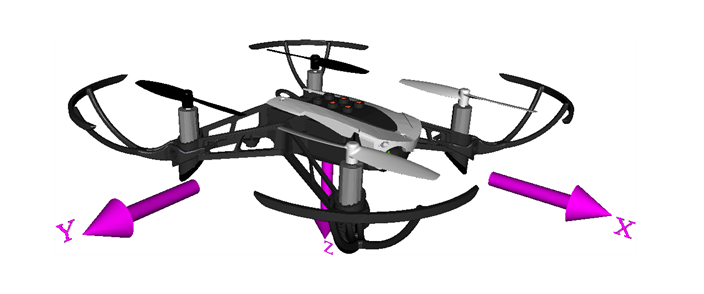

### Governing Equations for Each Propeller

The resulting equations, for each propeller, are:

- $F_z =k_t \omega^2$                      The force created by the propeller is in the z-direction  (Body frame of reference)

- $M_z =k_m \omega^2$                    The torque that is created by the motor and propeller spinning is also in the z-direction  (Body frame of reference)

## UAV Parameters

In order to understand how a quadcopter works, you need to understand the forces the propellers create, as well as  several parameters associated with the quadcopter UAV itself.  These include:

- the description of the geometry of the quadcopter UAV, including the location of the propellers

- the distribution of mass over the quadcopter UAV geometry

In this lesson, you will review each of these and learn how they are incorporated into the UAV flight parameters, and eventually the control system.

### Example

#### Characterizing the Distribution of Mass

As an example, consider a simplified model of a UAV.     In this model, the UAV consists of five point masses.    You can see the top down view and the side view.

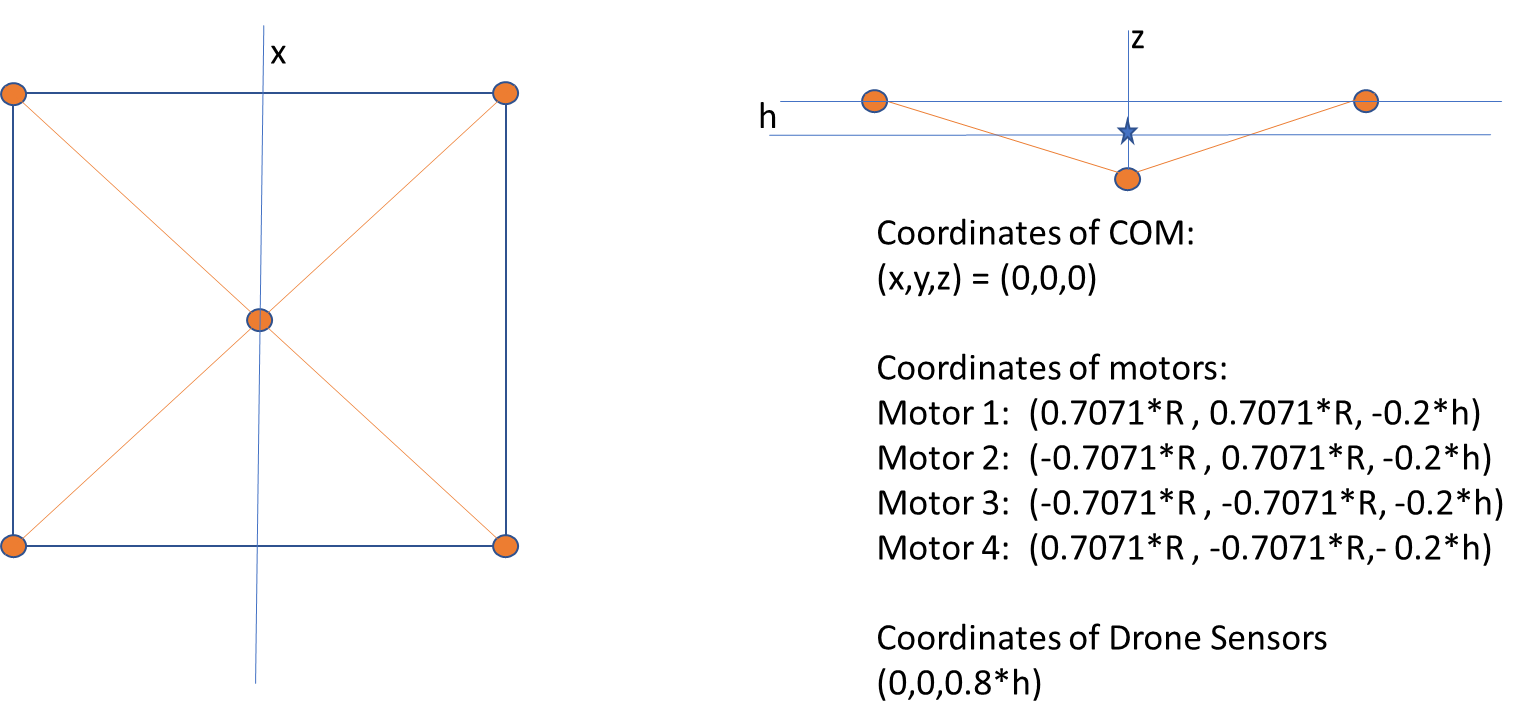

- The CPU and sensors.    Location:  $X_0 =\left\lbrack \begin{array}{ccc}
0 & 0 & \frac{4h}{5}
\end{array}\right\rbrack$            Mass:    $m_0 =0\ldotp 2m$

- Propellor 1.                      Location:  $X_1 =\left\lbrack \begin{array}{ccc}
\frac{R}{\sqrt{2}} & \frac{R}{\sqrt{2}} & -\frac{h}{5}
\end{array}\right\rbrack$          Mass:    $m_0 =0\ldotp 2m$

- Propellor 2.                      Location:  $X_2 =\left\lbrack \begin{array}{ccc}
\frac{-R}{\sqrt{2}} & \frac{R}{\sqrt{2}} & -\frac{h}{5}
\end{array}\right\rbrack$          Mass:    $m_0 =0\ldotp 2m$

- Propellor 3.                      Location:  $X_3 =\left\lbrack \begin{array}{ccc}
\frac{-R}{\sqrt{2}} & \frac{-R}{\sqrt{2}} & -\frac{h}{5}
\end{array}\right\rbrack$          Mass:    $m_0 =0\ldotp 2m$

- Propellor 4.                      Location:  $X_4 =\left\lbrack \begin{array}{ccc}
\frac{R}{\sqrt{2}} & \frac{-R}{\sqrt{2}} & -\frac{h}{5}
\end{array}\right\rbrack$          Mass:    $m_0 =0\ldotp 2m$

Given the geomtery and the mass distribution, you can calculate total mass, the center of mass and the moments of inertia.

#### The Center of Mass

The center of mass is found by a volume integral over the body.   The vector r points to the differential mass element dm.


$$\textrm{CoM}=\int \int \int r\;\textrm{dm}$$


We need to identify the location of our mass elements.

m=0.0638;  h=0.01;  R=0.05;

% Coordinates of Masses 
X0=[ 0         ,  0         , 4*h/5]; % position of sensors
X1=[ R/sqrt(2) ,  R/sqrt(2) ,    -h/5]; % position of propeller 1
X2=[ R/sqrt(2) , -R/sqrt(2) ,    -h/5]; % position of propeller 2
X3=[-R/sqrt(2) , -R/sqrt(2) ,    -h/5]; % position of propeller 3
X4=[-R/sqrt(2) ,  R/sqrt(2) ,    -h/5]; % position of propeller 4

dm0=m/5;
dm1=m/5;
dm2=m/5;
dm3=m/5;
dm4=m/5;


#### Calculation of Center of Mass

The Center of Mass is then:


$$\textrm{CoM}=\sum_i X_i m_i =\left\lbrack \begin{array}{ccc}
0 & 0 & 0
\end{array}\right\rbrack$$



CoM=X0*dm0 + X1*dm1 + X2*dm2 + X3*dm3 + X4*dm4;
disp(CoM)

     0     0     0



#### Total Mass

The Mass is then:


$$m=\sum_i m_i =0\ldotp 0638$$


m=dm0 + dm1 + dm2 + dm3 + dm4;
disp(m)

    0.0638



#### The Moments of Inertia

The moments of inertia needed for the airframe model are

   
$$I=\left\lbrack \begin{array}{ccc}
I_{\textrm{xx}}  & {-I}_{\textrm{xy}}  & {-I}_{\textrm{xz}} \\
{-I}_{\textrm{yx}}  & I_{\textrm{yy}}  & {-I}_{\textrm{yz}} \\
{-I}_{\textrm{zx}}  & {-I}_{\textrm{zy}}  & I_{\textrm{zz}} 
\end{array}\right\rbrack$$


where its elements are all functions of the geometry of the UAV. 


$$I_{\textrm{xy}} =I_{\textrm{yx}} =\int \int \int xy\;\textrm{dm}$$
   


$$I_{\textrm{xz}} =I_{\textrm{zx}} =\int \int \int x\;z\;\textrm{dm}$$
  


$$I_{\textrm{zy}} =I_{\textrm{yz}} =\int \int \int y\;z\;\textrm{dm}$$
  


$$I_{\textrm{xx}} =\int \int \int \left(y^2 +z^2 \right)\;\textrm{dm}$$
  


$$I_{\textrm{yy}} =\int \int \int \left(x^2 +z^2 \right)\;\textrm{dm}$$



$$I_{\textrm{zz}} =\int \int \int \left(x^2 +y^2 \right)\;\textrm{dm}$$


In these integrals, dm is the differential mass with coordinates (x,y,z)

#### Calculation of Moments of Inertia

You can calculate these (and you will need to when you run this system for your own UAV!).   Your calculation will be an integration over the UAV body, with "dm" being a differential mass element and (x,y,z) pointing to that differential mass from the CoM of the UAV.   This calculation gives you the information you need about how the mass is distributed about the UAV.

For your simple point-mass model, the Moments of Inertia are reduced to finite sums and 

Ixy=X0(1)*X0(2)*dm0 + X1(1)*X1(2)*dm1 + X2(1)*X2(2)*dm2 + X3(1)*X3(2)*dm3 + X4(1)*X4(2)*dm4;
Iyz=X0(3)*X0(2)*dm0 + X1(3)*X1(2)*dm1 + X2(3)*X2(2)*dm2 + X3(3)*X3(2)*dm3 + X4(3)*X4(2)*dm4;
Ixz=X0(1)*X0(3)*dm0 + X1(1)*X1(3)*dm1 + X2(1)*X2(3)*dm2 + X3(1)*X3(3)*dm3 + X4(1)*X4(3)*dm4;
disp([Ixy,Iyz,Ixz]); 

     0     0     0




Ix2=X0(1)*X0(1)*dm0 + X1(1)*X1(1)*dm1 + X2(1)*X2(1)*dm2 + X3(1)*X3(1)*dm3 + X4(1)*X4(1)*dm4;
Iy2=X0(2)*X0(2)*dm0 + X1(2)*X1(2)*dm1 + X2(2)*X2(2)*dm2 + X3(2)*X3(2)*dm3 + X4(2)*X4(2)*dm4;
Iz2=X0(3)*X0(3)*dm0 + X1(3)*X1(3)*dm1 + X2(3)*X2(3)*dm2 + X3(3)*X3(3)*dm3 + X4(3)*X4(3)*dm4;
Ixx=Iy2+Iz2;  Iyy=Ix2+Iz2;   Izz=Ix2+Iy2;
disp(Ixx)

   6.4821e-05



disp(Iyy)

   6.4821e-05



disp(Izz)

   1.2760e-04



So the results of the simplistic model are:


$$I_{\textrm{xx}} =I_{\textrm{yy}} =6\ldotp 5\;\;*{10}^{-5} \;\textrm{kg}*{\textrm{meters}}^2$$



$$I_{\textrm{zz}} =1\ldotp 3*{10}^{-4} \;\textrm{kg}*{\textrm{meters}}^2$$


The Model for the Parrott Mambo Drone gives 


$$I_{\textrm{xx}} =5\ldotp 8\;\;*{10}^{-5} \;\textrm{kg}*{\textrm{meters}}^2$$



$$I_{\textrm{yy}} =7\ldotp 2\;\;*{10}^{-5} \;\textrm{kg}*{\textrm{meters}}^2$$



$$I_{\textrm{zz}} =1\ldotp 0\;\;*{10}^{-4} \;\textrm{kg}*{\textrm{meters}}^2$$


and as this is reasonably close to the simple five-point-mass model, you can intuitively understand the representation.

### Solid Models

Model-based design often involves the modeling of a set of features on one software platform for use on another.   In thnis case, a solid model of your actual drone can be assembled in a wide variety of software packages and the results ported into MATLAB for flight analysis. The important thing for your MATLAB simulation is that you have a good model of the mass and the moments of inertia of the UAV.

## The Propeller System

### Torques created by Propellers

Since the propellers are not located at the quadcopter center of mass, each motor and propeller assembly creates torques that act upon the center of mass of the UAV as well.      

The torque that results from the motor creating a thrust in the z-direction from its location offset from the UAV center of mass is


$$M=r\times F_z$$


You have four propellers, so the sum of the moments can be written


$$M=\sum_{n=1}^4 r_n \times F_n$$


### Summary of Applied Forces

Summarizing the forces and torques created by the individual propellers and the torques created due to the propellers being offset from the center of mass, you obtain.


$$F=\sum_{n=1}^4 F_{z,n}$$



$$M=\sum_{n=1}^4 M_{z,n} +\sum_{n=1}^4 r_n \times F_n$$


Where again,

- $F_z =k_t \omega^2$                      The force created by the propeller is in the z-direction  (Body frame of reference)

- $M_z =k_m \omega^2$                    The torque that is created by the motor and propeller spinning is also in the z-direction  (Body frame of reference)

So, once you have characterized the constant coefficients associated with each motor-propeller assembly, and you control the angular velocity each motor spins, you control the aggregate forces and torques that drive the motion of your UAV.

### Practical Limits on Thrust (force) Created by Propellers

To create a torque to cause the UAV to tilt requires that you spin some motors faster than others.     Of course you would never want to command a propeller to change the direction it is spinning.   All the control you need can be achieved by speeding up, or slowing down, propellers from their nominal speed.

You have seen in a previous lesson that eventually you will use a feed-forward system.   You can think of this as spinning the propellers uniformally to the velocity where their combined force will compensate for gravity.   The changes you make to the angular velocity of any propellor is just a deviation from that nominal, feed-forward, velocity.

The feed-forward force was:


$$F_{\textrm{fwd},\textrm{total}} =-\textrm{mg}$$


With each of the four propellers providing 


$$F_{\textrm{fwd}} =-\frac{\textrm{mg}}{4}$$


It is reasonable to assume that your drone has the ability to hover.   For purposes of this design, the assumption will be that the four propellers together can create forces that would be in the range


$$-2\textrm{mg}\le F_z \le 0$$


Each of the four propellers then provides thrust in the range of 


$$-\frac{\textrm{mg}}{2}\le F_z \le 0$$


Since the feed forward force is combined with the applied thrust T, the limits on the applied thrust can be found to be


$$F_z =F_{\textrm{fwd}} +T$$


and so, the controllable portion of the force can be expressed as


$$-\frac{\textrm{mg}}{4}\le T\le \frac{\textrm{mg}}{4}$$


## Exercises

- Use the simple model above and adjust the weights of the sensors and motors, and position of the sensors assembly to more closely match the mass and moments of inertia of the Parrott Minidrone.

% Your code goes here:



## The Motor Mixing Algorithm

The Motor-Mixing Algorithm takes as input the desired thrust, roll, pitch and yaw quantities and transforms them into the speeds that each of the four quadcopter propellers must spin.   This discussion starts with a review of Euler Angles

### Euler Angles

Below is an illustration of how the Euler Angles describe the orientation (i.e. the attitude). of the quadcopter.   In summary the angles measure:

- Roll (rotation about the x-axis)

- Pitch (rotation about the y-axis)

- Yaw (rotation about the z-axis)

in each case the convention is to follow the right hand rule, so for example, if the roll angle is positive the y-axis moves in the direction of the positive z-axis).   Remember that in our body frame, the z-axis points toward the earth and the x-axis points towards the front of the quadcopter.

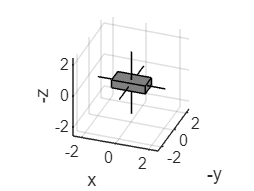

addpath('utils');

% Euler Angles
phi =  0 ;    % Roll
thta = 0;    % Pitch
psi =  0;     % Yaw

RotateBoxPlot(phi,thta,psi);

### Roll and Pitch

As you look at the geometry of the quadcopter, you can see that to achieve rotations about these axis, you need to control the propeller speeds accordingly.

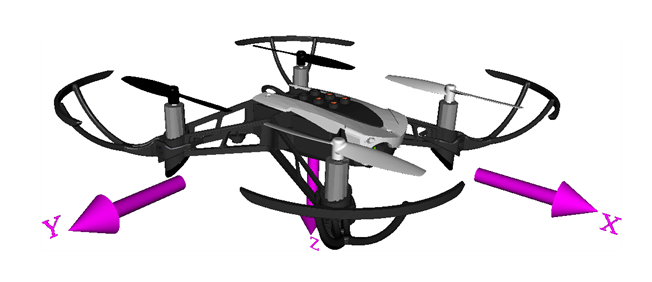

- Roll.     Slow down propellers 1 and 2;   Speed up propellers 3 and 4;

- Pitch    Slow down propellers 1 and 4;   Speed up propellers 2 and 3

### 

### Yaw

Yaw is a bit more complex.    When you spin a propeller there is a torque applied to the center of mass of vehicle.     To control this, the quadcopter is designed so that the propellers alternate their direction of rotation as you proceed around the vehicle.    The pair of propellers at opposite sides of the orgin from one another spin in the same direction.

- Yaw.    Slow down propellers 2 and 4;   Speed up propellers 1 and 3.

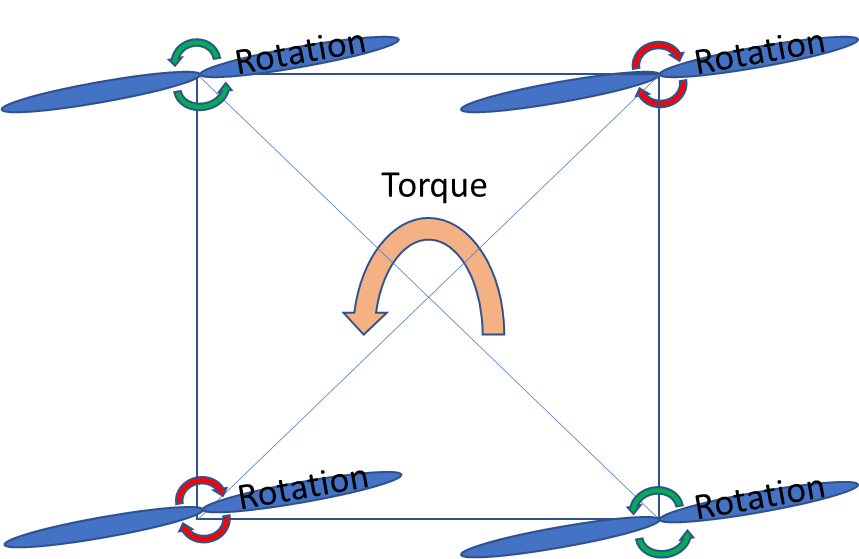

### The Motor-Mixing Matrix

Combining Roll, Pitch and Yaw with what you already knew about Thrust gives you a set of four maneuvers you can make given the four propeller speed controls you can control.    This gives the Motor Mixing Matrix.    If your input is Thrust, Roll, Pitch and Yaw, you can calculate changes necessary in each of the individual propeller speeds.


$$2v_0 \left\lbrack \begin{array}{c}
v_1 \\
v_2 \\
v_3 \\
v_4 
\end{array}\right\rbrack =\frac{1}{2}\left\lbrack \begin{array}{cccc}
1 & -1 & -1 & 1\\
1 & -1 & 1 & -1\\
1 & 1 & 1 & 1\\
1 & 1 & -1 & -1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
T\\
R\\
P\\
Y
\end{array}\right\rbrack$$


The factor of 1/2 scales the motor-mixing matrix so that its inverse is equal to its transpose.    Each of these commands is independent of the other.   You can see that intuitively.   Consider Yaw, for example.   By inducing a yaw by increasing the velocity of propellers 1 and 4 by the same amount you reduce the velocity of propellers 2 and 3, the thrust remains the same, and you don't induce either a roll or a pitch.   The fact that the inverse of the motor-mixing matrix is the same as its transpose is a result of this fact,

A=[1 -1 -1 1;1 -1 1 -1;1 1 1 1;1 1 -1 -1]/2

A =     0.5000   -0.5000   -0.5000    0.5000
    0.5000   -0.5000    0.5000   -0.5000
    0.5000    0.5000    0.5000    0.5000
    0.5000    0.5000   -0.5000   -0.5000


A'*A    % this product results in the identity matrix

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


### Implementation in Simulink.

The implementation of the motor-mixing function in Simulink can be done a couple of different ways.   You can define a function, or you can simply build a subsystem and use the matrix multiplication block already build into Simulink.

### Relating the Motor-Mixing Algorithm to the Applied Forces

In the paragraph above you saw that

$A=\frac{1}{2}\left\lbrack \begin{array}{cccc}
1 & -1 & -1 & 1\\
1 & -1 & 1 & -1\\
1 & 1 & 1 & 1\\
1 & 1 & -1 & -1
\end{array}\right\rbrack$      Then $2v_0 \left\lbrack \begin{array}{c}
v_1 \\
v_2 \\
v_3 \\
v_4 
\end{array}\right\rbrack =A\left\lbrack \begin{array}{c}
T\\
R\\
P\\
Y
\end{array}\right\rbrack$    and correspondingly   $2v_0 A^T \left\lbrack \begin{array}{c}
v_1 \\
v_2 \\
v_3 \\
v_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
T\\
R\\
P\\
Y
\end{array}\right\rbrack$

and in an earlier section you saw that


$$F=\sum_{n=1}^4 F_{z,n}$$



$$M=\sum_{n=1}^4 M_{z,n} +\sum_{n=1}^4 r_n \times F_n$$


Remember that this was all written in the body-frame coordinate system, so:


$$F=T$$



$$M_x =R$$



$$M_y =P$$



$$M_z =Y$$


This is important.      For a simulation, you can choose which set of equations to include.  As you start to work with an actual quadcopter UAV, the physical drone behaves according to the rules you derived from the fundamental physics.     On the other hand, the controller you will program to control the system will use the motor-mixing matrix.

## Building the quadcopter model in Simulink

At this point you are ready to build your Simulink model of a quadcopter.  

### Objective of Quadcopter Simulink Model

Based on the plan presented at the beginning of the lession, you want to change the inputs so that they are propeller velocities inad you want to create a function to convert the propeller / motor function into the forces and torques that are applied to the airframe.

### Steps:

- Open the airframe model from the end of the first module

- Create a Simulink subsystem to generate the forces resulting from propellers

- Run the model and visualize the result using the same Simscape multibody model

- Adjust the parameters for the lift generation so that the quadcopter hovers

## Exercises:  

Working with the quadcopter model

- Complete the addition of the propeller/motor function to your model

- Tune the propeller forcing by hand so that the quadcopter (nearly) hovers

- Motivate the need for a control system by placing an external forcing on the quadcopter

% A Simulink Exercise